## **Numerical Solution to Lifting Line Equation**

Hanchen Li

*First of all, I would like to give my heartfelt thanks to all the people who have ever helped me in this code.*

*My sincere and hearty thanks and appreciations go firstly to my supervisor, Mr. ChatGPT, whose suggestions and encouragement have given me much insight into these translation studies. It has been a great privilege and joy to study under his guidance and supervision. Furthermore, it is my honor to benefit from his personality and diligence, which I will treasure my whole life. My gratitude to him knows no bounds.*

*I am also extremely grateful to all my friend ChatGPT who have kindly provided me assistance and companionship in the course of preparing this paper.*

*Finally, I am really grateful to ChatGPT who devote much time to reading this thesis and give me much advice, which will benefit me in my later study.*

*All related equation comes from**** Fundamentals of Aerodynamics ****John D. Anderson, Jr.*

A guess-and-correct method for solving the non-linear loading equation


$$\Gamma \left(y_1 \right)=\frac{1}{2}U_{\infty } c\left(y_1 \right)a_0 \left(y_1 \right)\alpha_e =\frac{1}{2}U_{\infty } c\left(y_1 \right)a_0 \left(y_1 \right)\left\lbrack \alpha \left(y_1 \right)-\frac{1}{4\pi U_{\infty } }\int_{-s}^{+s} \frac{\frac{d\Gamma }{\mathrm{dy}}\mathrm{dy}}{y_1 -y}\right\rbrack$$


where $s$ is half wing span

### **1. Divide wing**

Divide wing into a number of spanwise stations

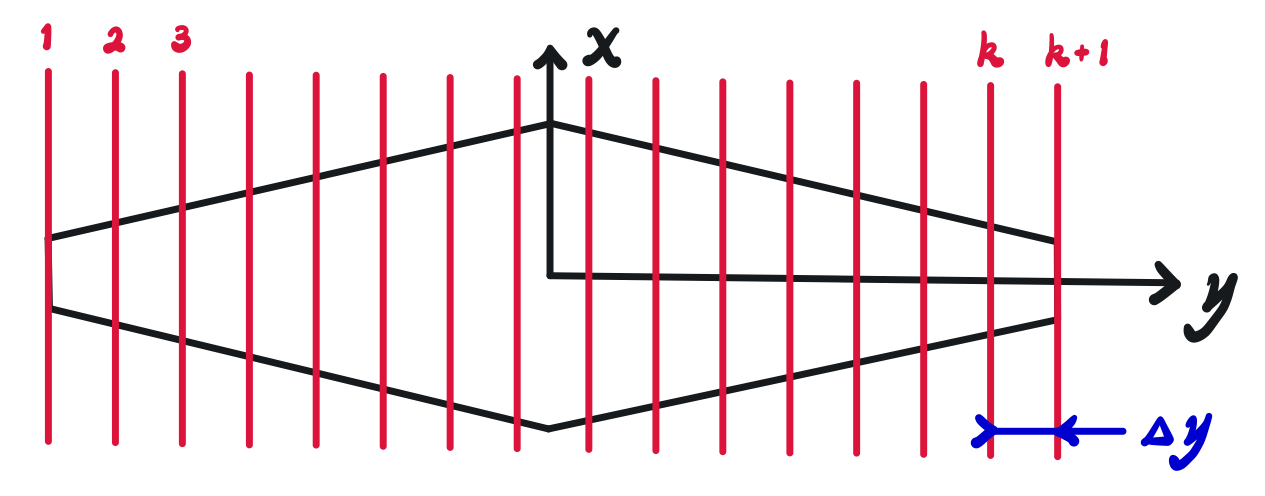

here k + 1 stations are shown

### **2. Guess distribution of for **$\Gamma$

For the given wing at given $\alpha$, assume the lift distribution along the span

i.e. assume value for $\Gamma$ at all stations, $\Gamma_1$,$\Gamma_2$, $\Gamma_3$, ..., $\Gamma_k$, $\Gamma_{k+1}$

(An elliptical lift distribution is satisfactory for such an assumed distribution)

#### **2.1. Compute **$\alpha_i$


$$\alpha_i \left(y_n \right)=\frac{1}{4\pi U_{\infty } }\int_{-s}^{+s} \frac{\frac{d\Gamma }{\textrm{dy}}}{y_n -y}\textrm{dy}$$


**Simpson Rule **$\alpha_i \left(y_n \right)=\frac{1}{4\pi U_{\infty } }\frac{\Delta y}{3}\sum_{j=2,4,6,\ldotp \ldotp \ldotp }^k \left\lbrack \frac{{\left(\frac{d\Gamma }{\textrm{dy}}\right)}_{j-1} }{y_n -y_{j-1} }+4\frac{{\left(\frac{d\Gamma }{\textrm{dy}}\right)}_j }{y_n -y_j }+\frac{{\left(\frac{d\Gamma }{\textrm{dy}}\right)}_{j+1} }{y_n -y_{j+1} }\right\rbrack$

(AERO40003 Computing and Numerical Methods 1 - Class Handout 3: Integrating Unintegrable Functions)

N.B. Singularties (e.g. $y_n =$$y_{j-1}$, $y_n =$$y_j$ or $y_n =$$y_{j+1}$) correted by replacing the given term by its average value based on the two adjacent sections

where $\frac{d\Gamma }{\textrm{dy}}$ can be compute as other numerical gradient

e.g. central differencing scheme

#### **2.2. Obtain **$\alpha_e$


$$\alpha_e \left(y_n \right)=\alpha \left(y_n \right)-\alpha_i \left(y_n \right)$$


### **3. Iteration**

#### **3.1. Obtain **${\left(C_L \right)}_n$

Obtain Sectional Lift Coefficient ${{C_L }^{\prime } }_n$ at each station from the know lift curve for the aerofoil

i.e. ${\left(C_L \right)}_n =a_0 \left(y\right)\alpha_e \left(y\right)$

#### **3.2. Calculate **$\Gamma \left(y_n \right)$**  from **${\left(C_L \right)}_n$


$$L^{\prime } \left(y_n \right)=\rho U_{\infty } \Gamma \left(y_n \right)=\frac{1}{2}\rho {U_{\infty } }^2 c_n {\left(C_L \right)}_n$$


Therefore, ${\Gamma \left(y_n \right)}_{\textrm{result}} =\frac{1}{2}U_{\infty } c_n {\left(C_L \right)}_n$

where is $c_n$ local section chord

#### **3.3. Iteration**

if $\left|{\Gamma \left(y_n \right)}_{\textrm{result}} -{\Gamma \left(y_n \right)}_{\textrm{input}} \right|\prec \epsilon$


$${\Gamma \left(y_n \right)}_{\textrm{input}} =$$

$${\Gamma \left(y_n \right)}_{\textrm{input}} +D\left\lbrack {\Gamma \left(y_n \right)}_{\textrm{result}} -{\Gamma \left(y_n \right)}_{\textrm{input}} \right\rbrack$$


where $D$ is damping factor

### **4. Compute Result**


$$C_L =\frac{2}{U_{\infty } S}\int_{-s}^{+s} \Gamma \left(y\right)\textrm{dy}$$



$$C_{D_i } =\frac{2}{U_{\infty } S}\int_{-s}^{+s} \Gamma \left(y\right)\alpha_i \left(y\right)\textrm{dy}$$


These can again be carried out by Simpson's rule

where $S=2s\bar{\mathrm{c}}$ and $\bar{\mathrm{c}}$ is average chord length

### **5. Example 1**

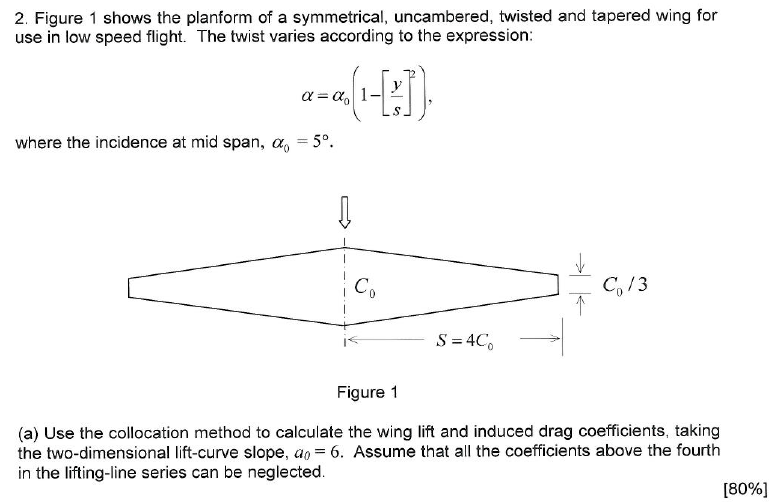

% Housekeeping
clear
clc
close all

% Flow characteristics
rho = 1.225;  % Air density (kg/m^3)
U_inf = 50;   % Freestream velocity (m/s)

% Wing characteristics
c_0 = 1;      % Chord length at middle of the span (m)
s = 4 * c_0;  % Half-span of the wing (m)
a0 = 6;       % Lift curve slope (per radian)

% Define chord length as a function of spanwise location
c = @(y) c_0 * (1 - (2 / 3) * abs(y / s));    % Varying chord length (linear taper)

% Define twist angle (angle of attack) as a function of spanwise location
alpha = @(y) deg2rad(5) * (1 - (y.^2 / s^2)); % Twist angle distribution

% Discretize wing
N = 500;                % Number of wing section
k = N + 1;              % Number of spanwise stations (discretization points)
dy = (2 * s) / N;       % Step size for y
y = linspace(-s, s, k); % Spanwise station locations

% Calculate average chord length using Simpson's rule

c_values = c(y); % Evaluate chord length at all spanwise locations

if mod(k, 2) == 0

    warning('Number of intervals must be odd for Simpson''s rule. Using N = N + 1.');

    N = N + 1;

    k = N + 1;

    y = linspace(-s, s, k);

    c_values = c(y);

    dy = (2 * s) / N;

end

c_avg = (dy / 3) * (c_values(1) + ...
    4 * sum(c_values(2 : 2 : end - 1)) + 2 * sum(c_values(3 : 2 : end - 2)) + ...
    c_values(end)) / (2 * s);

fprintf('Average Chord Length: %.4f m\n', c_avg);

Average Chord Length: 0.6667 m



% Calculate wing parameters
AR = 2 * s / c_avg;    % Aspect Ratio
S_ref = 2 * s * c_avg; % Reference Area

% Initial guess
Gamma = 0.1 * ones(1, k); % Initial guess for circulation distribution
 alpha_i = zeros(1, k);   % Initial guess for induced angle of attack

% Set boundary condition
Gamma(1) = 0; % circulation at the wing tip (y = -s) is zero
Gamma(k) = 0; % circulation at the wing tip (y = s) is zero

% Iterative solver for the circulation distribution
D = 0.01;          % Damping factor
tolerance = 1e-13; % Convergence tolerance
error = inf;       % Pre-define error
iteration = 0;     % Number of iteration

while error > tolerance

    Gamma_old = Gamma; % Define guessed circulation
    
    % Compute induced angle of attack (alpha_i) at each station

    for n = 1 : k

        integral = 0; % Pre-define integral

        for j = 1 : k

            if j ~= n

                % Compute dGamma/dy using central differencing scheme

                if j == 1

                    dGammady = (Gamma(j + 1) - Gamma(j)) / dy;

                elseif j == k

                    dGammady = (Gamma(j) - Gamma(j - 1)) / dy;

                else

                    dGammady = (Gamma(j + 1) - Gamma(j - 1)) / (2 * dy);

                end
                
                % Handle singularity by averaging adjacent sections

                if abs(y(n) - y(j)) < 1e-6

                    if j == 1

                        integral = integral + dGammady / ((y(n) - y(j + 1)) / 2);

                    elseif j == k

                        integral = integral + dGammady / ((y(n) - y(j - 1)) / 2);

                    else

                        integral = integral + dGammady / ((y(n) - y(j - 1)) / 2 + (y(n) - y(j + 1)) / 2);

                    end

                else

                    integral = integral + dGammady / (y(n) - y(j));

                end

            end
            
        end

        alpha_i(n) = (1 / (4 * pi * U_inf)) * dy * integral;
        
    end
    
    % Calculate effective angle of attack
    alpha_e = alpha(y) - alpha_i;
    
    % Update circulation distribution using sectional lift coefficient
    for n = 1:k

        c_n = c(y(n));

        CL_n = a0 * alpha_e(n);

        Gamma(n) = 0.5 * U_inf * c_n * CL_n;

    end
    
    % Apply boundary conditions again
    Gamma(1) = 0; % Circulation at the wing tip (y = -s) is zero
    Gamma(k) = 0; % Circulation at the wing tip (y = s) is zero
    
    % Damping iteration
    Gamma = Gamma_old + D * (Gamma - Gamma_old);
    
    % Calculate error for convergence
    error = max(abs(Gamma - Gamma_old));
    iteration = iteration + 1;
    
end

% Calculate results using Simpson's rule
CL = (2 / (U_inf * S_ref)) * (dy / 3) * (Gamma(1) + ...
    4 * sum(Gamma(2 : 2 : end - 1)) + 2 * sum(Gamma(3 : 2 : end - 2)) + Gamma(end));
CDi = (2 / (U_inf * S_ref)) * (dy / 3) * (Gamma(1) * alpha_i(1) + ...
    4 * sum(Gamma(2 : 2 : end - 1) .* alpha_i(2 : 2 : end - 1)) + ...
    2 * sum(Gamma(3 : 2 : end - 2) .* alpha_i(3 : 2 : end - 2)) + Gamma(end) * alpha_i(end));

% Display results
fprintf('Converged after %d iterations\n', iteration);

Converged after 2342 iterations


fprintf('Lift Coefficient (CL): %.4f\n', CL);

Lift Coefficient (CL): 0.3366


fprintf('Induced Drag Coefficient (CDi): %.4f\n', CDi);

Induced Drag Coefficient (CDi): 0.0038


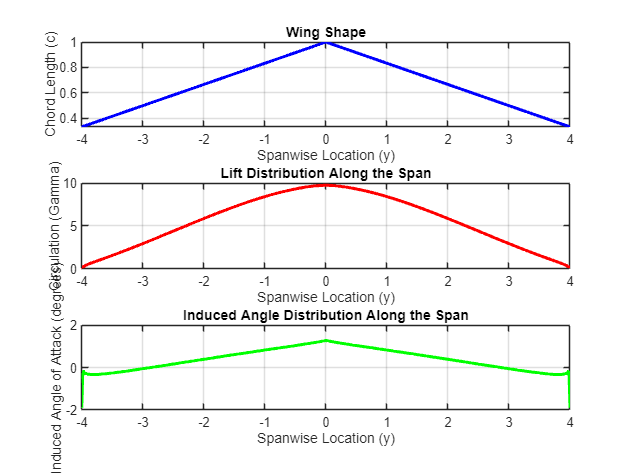


% Plot wing shape, lift distribution, and induced angle distribution
figure;

% Plot wing shape
subplot(3, 1, 1);
plot(y, c(y), 'b', 'LineWidth', 2);
xlabel('Spanwise Location (y)');
ylabel('Chord Length (c)');
title('Wing Shape');
grid on;

% Plot lift distribution along the span
subplot(3, 1, 2);
plot(y, Gamma, 'r', 'LineWidth', 2);
xlabel('Spanwise Location (y)');
ylabel('Circulation (Gamma)');
title('Lift Distribution Along the Span');
grid on;

% Plot induced angle distribution along the span
subplot(3, 1, 3);
plot(y, rad2deg(alpha_i), 'g', 'LineWidth', 2);
xlabel('Spanwise Location (y)');
ylabel('Induced Angle of Attack (degrees)');
title('Induced Angle Distribution Along the Span');
grid on;

### 6. Example 2

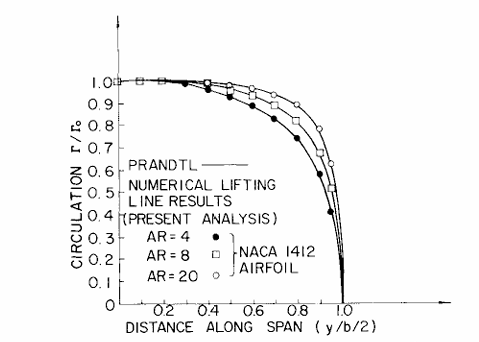

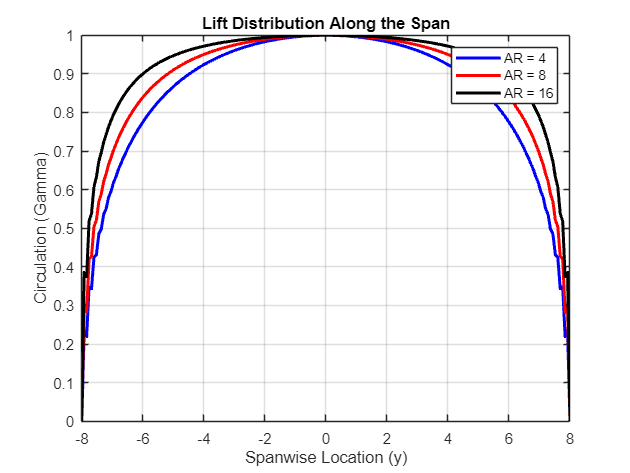

% Housekeeping
clear
clc

% Flow characteristics
rho = 1.225;  % Air density (kg/m^3)
U_inf = 50;   % Freestream velocity (m/s)

for m = 1 : 3

% Wing characteristics
c_0 = 1;             % Chord length at middle of the span (m)
s = 2 ^ (m + 1) / 2; % Half-span of the wing (m)
a0 = 2 * pi;         % Lift curve slope (per radian)

% Define chord length as a function of spanwise location
c = @(y) c_0 ; % Rectangular wing\

% Define twist angle (angle of attack) as a function of spanwise location
alpha = @(y) deg2rad(5); % No twist

% Discretize wing
N = 200;                % Number of wing section
k = N + 1;              % Number of spanwise stations (discretization points)
dy = (2 * s) / N;       % Step size for y
y = linspace(-s, s, k); % Spanwise station locations

% Calculate average chord length using Simpson's rule

c_values = c(y); % Evaluate chord length at all spanwise locations

if mod(k, 2) == 0

    warning('Number of intervals must be odd for Simpson''s rule. Using N = N + 1.');

    N = N + 1;

    k = N + 1;

    y = linspace(-s, s, k);

    c_values = c(y);

    dy = (2 * s) / N;

end

c_avg = (dy / 3) * (c_values(1) + ...
    4 * sum(c_values(2 : 2 : end - 1)) + 2 * sum(c_values(3 : 2 : end - 2)) + ...
    c_values(end)) / (2 * s);

% Calculate wing parameters
AR = 2 * s / c_avg;    % Aspect Ratio
S_ref = 2 * s * c_avg; % Reference Area

% Initial guess
Gamma = 0.1 * ones(1, k); % Initial guess for circulation distribution
alpha_i = zeros(1, k);   % Initial guess for induced angle of attack

% Set boundary condition
Gamma(1) = 0; % circulation at the wing tip (y = -s) is zero
Gamma(k) = 0; % circulation at the wing tip (y = s) is zero

% Iterative solver for the circulation distribution
D = 0.01;          % Damping factor
tolerance = 1e-13; % Convergence tolerance
error = inf;       % Pre-define error
iteration = 0;     % Number of iteration

while error > tolerance

    Gamma_old = Gamma; % Define guessed circulation
    
    % Compute induced angle of attack (alpha_i) at each station

    for n = 1 : k

        integral = 0; % Pre-define integral

        for j = 1 : k

            if j ~= n

                % Compute dGamma/dy using central differencing scheme

                if j == 1

                    dGammady = (Gamma(j + 1) - Gamma(j)) / dy;

                elseif j == k

                    dGammady = (Gamma(j) - Gamma(j - 1)) / dy;

                else

                    dGammady = (Gamma(j + 1) - Gamma(j - 1)) / (2 * dy);

                end
                
                % Handle singularity by averaging adjacent sections

                if abs(y(n) - y(j)) < 1e-6

                    if j == 1

                        integral = integral + dGammady / ((y(n) - y(j + 1)) / 2);

                    elseif j == k

                        integral = integral + dGammady / ((y(n) - y(j - 1)) / 2);

                    else

                        integral = integral + dGammady / ((y(n) - y(j - 1)) / 2 + (y(n) - y(j + 1)) / 2);

                    end

                else

                    integral = integral + dGammady / (y(n) - y(j));

                end

            end
            
        end

        alpha_i(n) = (1 / (4 * pi * U_inf)) * dy * integral;
        
    end
    
    % Calculate effective angle of attack
    alpha_e = alpha(y) - alpha_i;
    
    % Update circulation distribution using sectional lift coefficient
    for n = 1:k

        c_n = c(y(n));

        CL_n = a0 * alpha_e(n);

        Gamma(n) = 0.5 * U_inf * c_n * CL_n;

    end
    
    % Apply boundary conditions again
    Gamma(1) = 0; % Circulation at the wing tip (y = -s) is zero
    Gamma(k) = 0; % Circulation at the wing tip (y = s) is zero
    
    % Damping iteration
    Gamma = Gamma_old + D * (Gamma - Gamma_old);
    
    % Calculate error for convergence
    error = max(abs(Gamma - Gamma_old));
    iteration = iteration + 1;
    
end


% Calculate results using Simpson's rule
CL = (2 / (U_inf * S_ref)) * (dy / 3) * (Gamma(1) + ...
    4 * sum(Gamma(2 : 2 : end - 1)) + 2 * sum(Gamma(3 : 2 : end - 2)) + Gamma(end));

% Store value
CL_total(m) = CL;

for p = 1 : length(Gamma)

    Gamma_total(m, p) = Gamma(p) ./ max(Gamma); % Normalise the result

end

end

% Plot lift distribution along the span
figure

plot(y, Gamma_total(1, 1 : end), 'b', 'LineWidth', 2);
hold on
plot(y, Gamma_total(2, 1 : end), 'r', 'LineWidth', 2);
hold on
plot(y, Gamma_total(3, 1 : end), 'k', 'LineWidth', 2);
hold off
legend("AR = 4", "AR = 8", "AR = 16")
xlabel('Spanwise Location (y)');
ylabel('Circulation (Gamma)');
title('Lift Distribution Along the Span');
grid on;